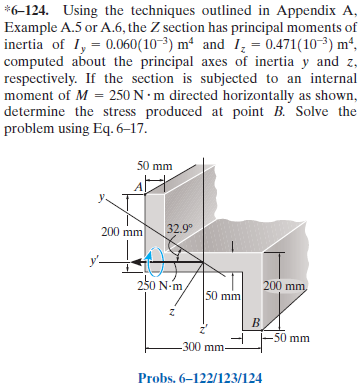

# symbolic units class

u = symunit;

# section properties

% ----------------------
% y-axis centroid
yc = [300-50/2 300/2 50/2]*u.mm;
Acz = [(200-50)*50 50*300 (200-50)*50]*u.mm^2;
Icz = [(200-50)*50^3 50*300^3 (200-50)*50^3]/sym(12)*u.mm^4;
[yn Qnz Inz] = beam.neutral_axis(yc, Acz, Icz); %#ok
Iz = sum(Inz);
% ----------------------
% z-axis centroid
zc = [(200-50)/2 200-50/2 200+(200-50)/2]*u.mm;
Acy = [50*(200-50) 300*50 50*(200-50)]*u.mm^2;
Icy = [50*(200-50)^3 300*50^3 50*(200-50)^3]/sym(12)*u.mm^4;
[zn Qny Iny] = beam.neutral_axis(zc, Acy, Icy); %#ok
Iy = sum(Iny);
% ----------------------
% product of inertia
Inyz = beam.Iyz(yc, zc, Acz, Icy, Icz);
Iyz = sum(Inyz);
% ----------------------
% principal moments of inertias
[Iyp Izp Iyzp thetap] = beam.Ip(Iy, Iz, Iyz); %#ok
Iyp = Iyp(1);
Izp = Izp(1);
% ----------------------

# normal stress and neutral axis orientation

% ----------------------
% bending moments
M = 250*u.N*u.m;
Myp = M*sin(thetap(2));
Mzp = M*cos(thetap(2));
% ---------------------
% bending location for point B
y = [yn -yn];
z = [-zn zn];
[yp zp] = beam.xyrot(y, z, thetap(1)); %#ok
% ---------------------
% bending stress and neutral axis orientation
[sigmap alphap] = beam.unsymmetric(Myp, Mzp, Iyp, Izp, yp, zp); %#ok
sigmap = rewrite(sigmap, u.kPa);
sigmap_vpa = vpa(sigmap, 3) %#ok

$$sigmap\_vpa = \left(\begin{array}{cc} -293.0\,\mathrm{kPa} & 293.0\,\mathrm{kPa} \end{array}\right)$$

alphap_vpa = vpa(alphap, 3) %#ok

$$alphap\_vpa = 85.3\,\deg$$

clear sigmap_vpa alphap_vpa;
% ---------------------